% Load ECG signals
load ECG_noisy.mat;
signal = ECG4_noisy;

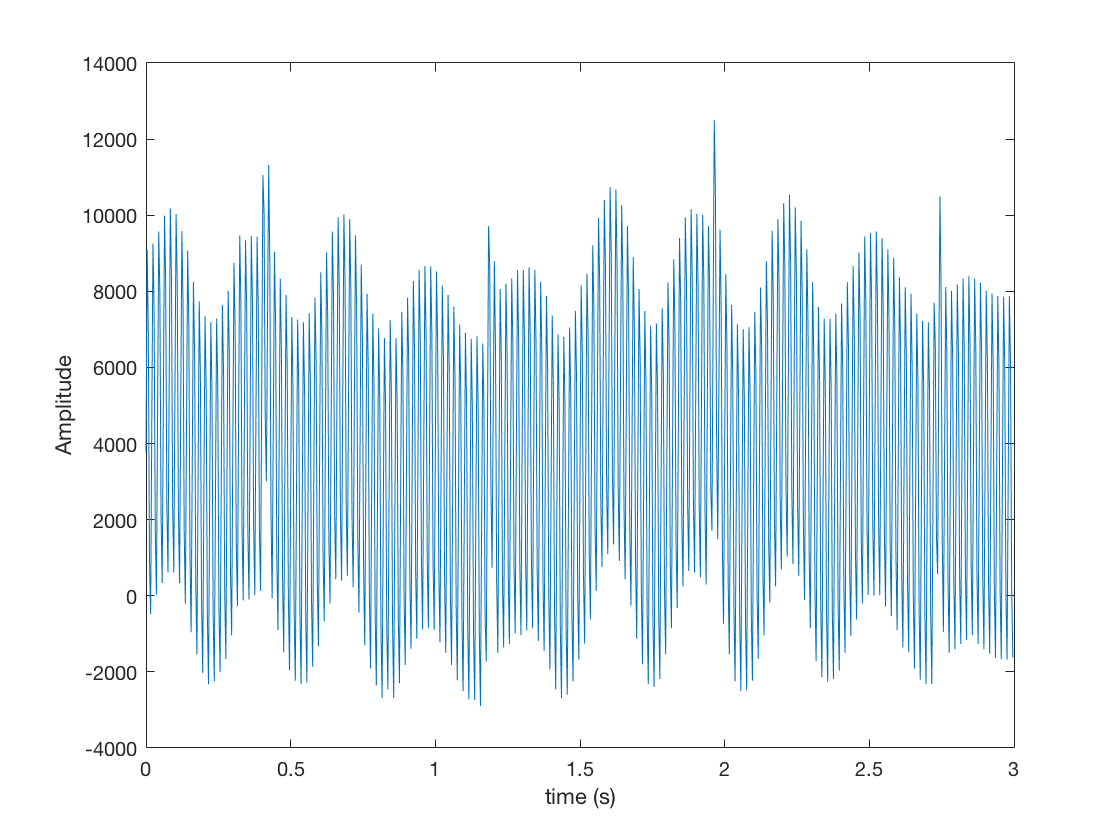

% Display the raw ECG signal.
end_t = 3;
time = 0:1/Fs:end_t-1/Fs;
figure(1)
plot(time,signal(1:end_t*Fs))
xlabel('time (s)')
ylabel('Amplitude')

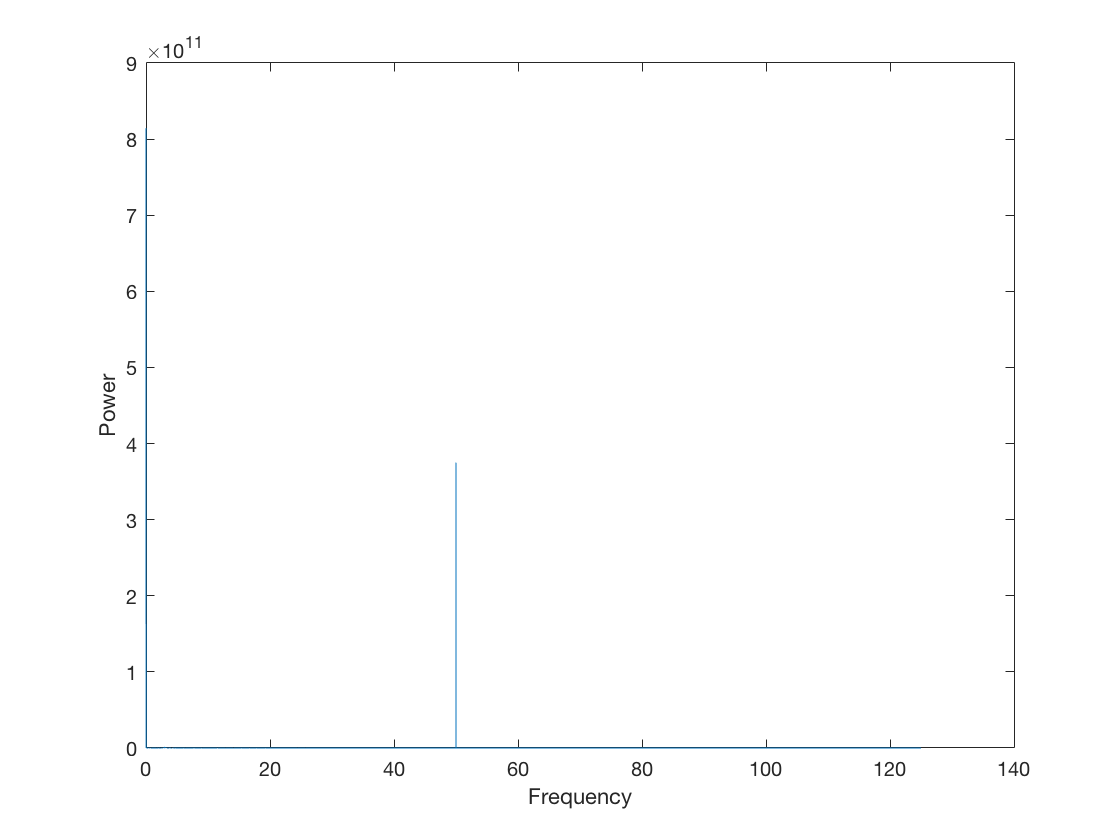

% Power spectual density of raw ECG signal.
figure(2)
y = fft(signal);     
n = length(signal);  
f = (0:n-1)*(Fs/n);  
power = abs(y).^2/n; 
plot(f(1:floor(n/2)),power(1:floor(n/2))) 
xlabel('Frequency')
ylabel('Power')

% Construct a low order butterworth high-pass filter to remove DC offset.
fc = 0.02;
fs = Fs;
[b,a] = butter(1,fc/(fs/2),'high');


% Apply the high-pass filter to the raw signal
signal_DC_removed = filter(b,a,signal);

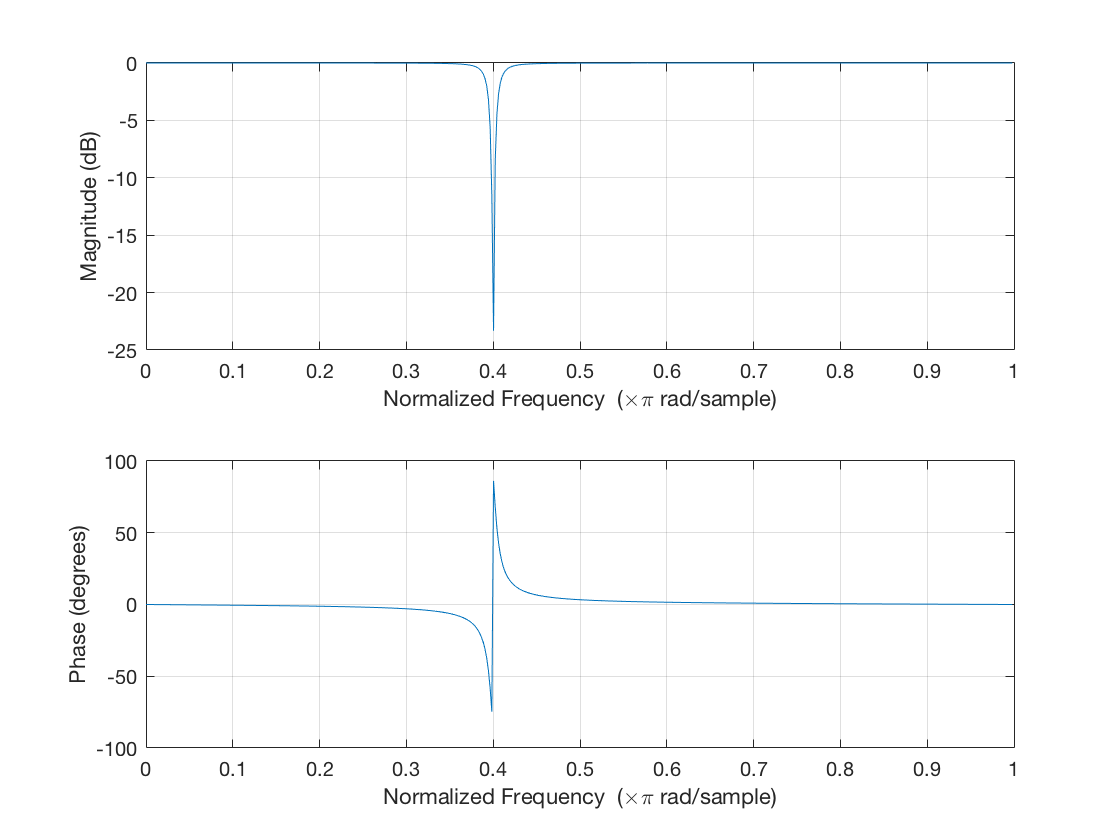

% ---------- For evaluation of baseline drift ------------------
% Construct a notch filter
noise_freq = 50;
wo = noise_freq/(fs/2);  
bw = wo/35;
[b,a] = iirnotch(wo,bw);
freqz(b,a)


% Apply the filter to the signal
signal_Power_line_filtered = filter(b,a,signal_DC_removed);

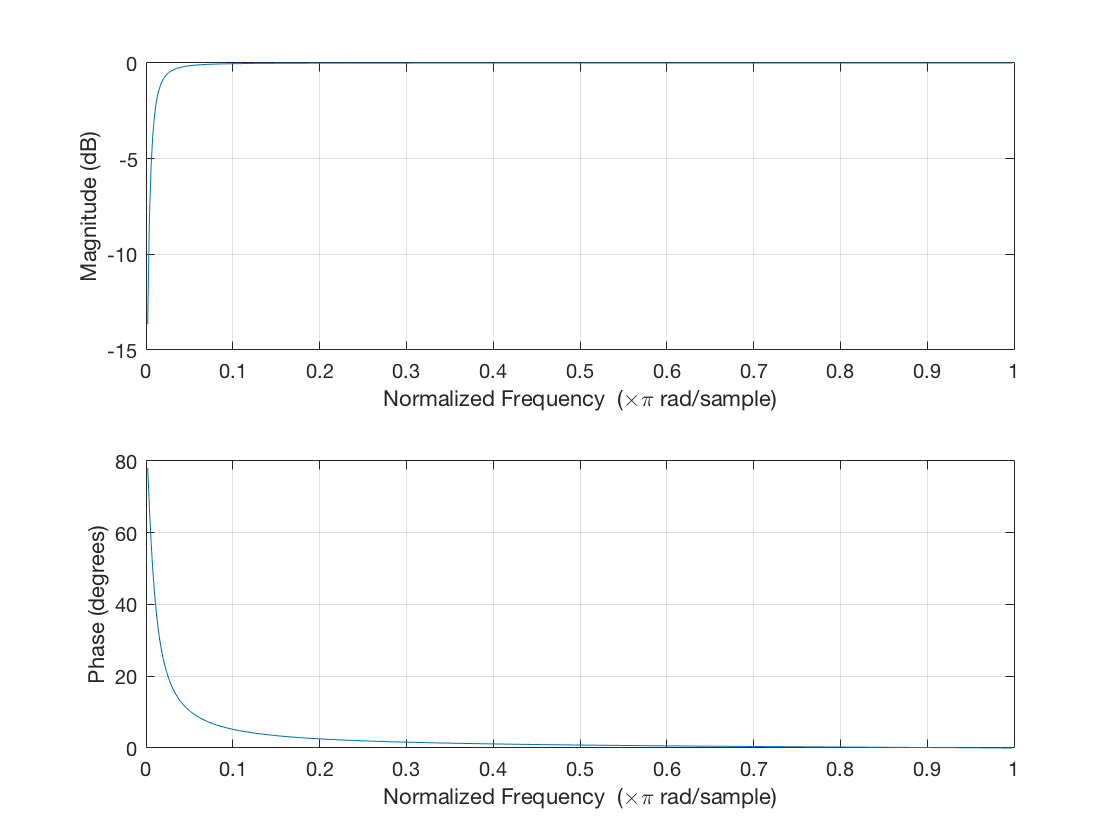

% Construct a low order butterworth high-pass filter to remove baseline drift.
fc = 1.15;
fs = Fs;
[b,a] = butter(1,fc/(fs/2),'high');

% Use freqz() to check the frequency response of the filter.
freqz(b,a);


% Apply the high-pass filter to the raw signal
signal_baseline_removed = filter(b,a,signal_Power_line_filtered);

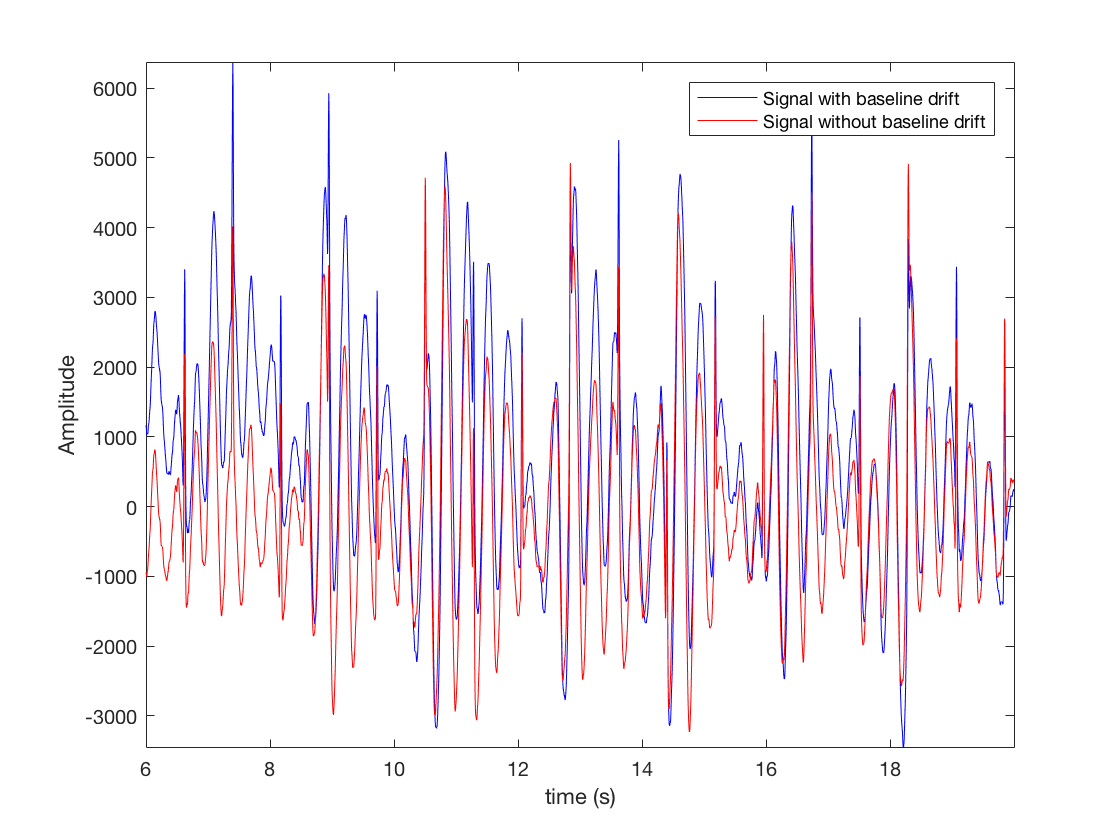

% Evaluate the baseline drift removal:
clf
N=length(signal_baseline_removed);
t=[0:N-1]/fs;   

figure(2)
plot(t(1500:5000),signal_Power_line_filtered(1500:5000),'b');  
hold on
axis tight
plot(t(1500:5000),signal_baseline_removed(1500:5000),'r'); 
legend('Signal with baseline drift','Signal without baseline drift')
xlabel('time (s)')
ylabel('Amplitude')

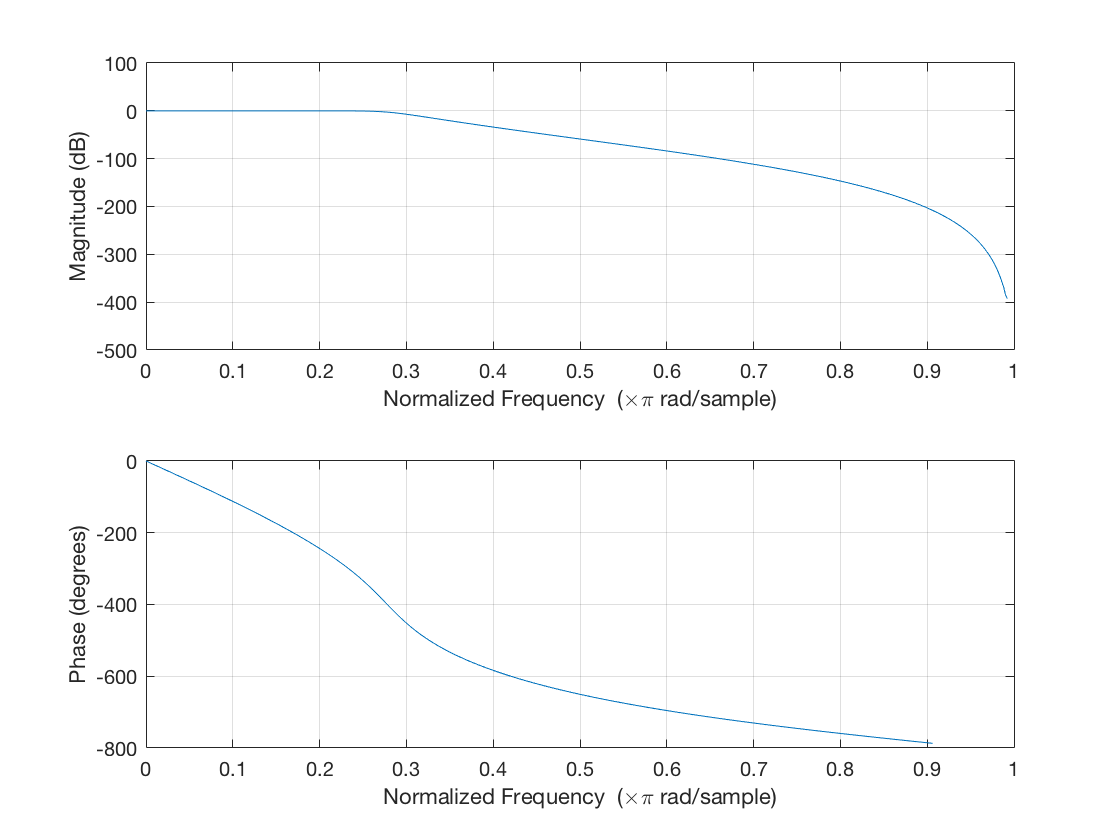

% Design of low pass filter:
fc = 35;
[b,a] = butter(9,fc/(fs/2),'low');
freqz(b,a)

signal_high_filtered = filter(b,a,signal_baseline_removed);

% Construct a notch filter
noise_freq = 50;
wo = noise_freq/(fs/2);  
bw = wo/35;
[b,a] = iirnotch(wo,bw);
freqz(b,a)


% Apply the filter to the signal
signal_Power_line_filtered = filter(b,a,signal_baseline_removed);

end_t = 3;
time = 0:1/Fs:end_t-1/Fs

time =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960


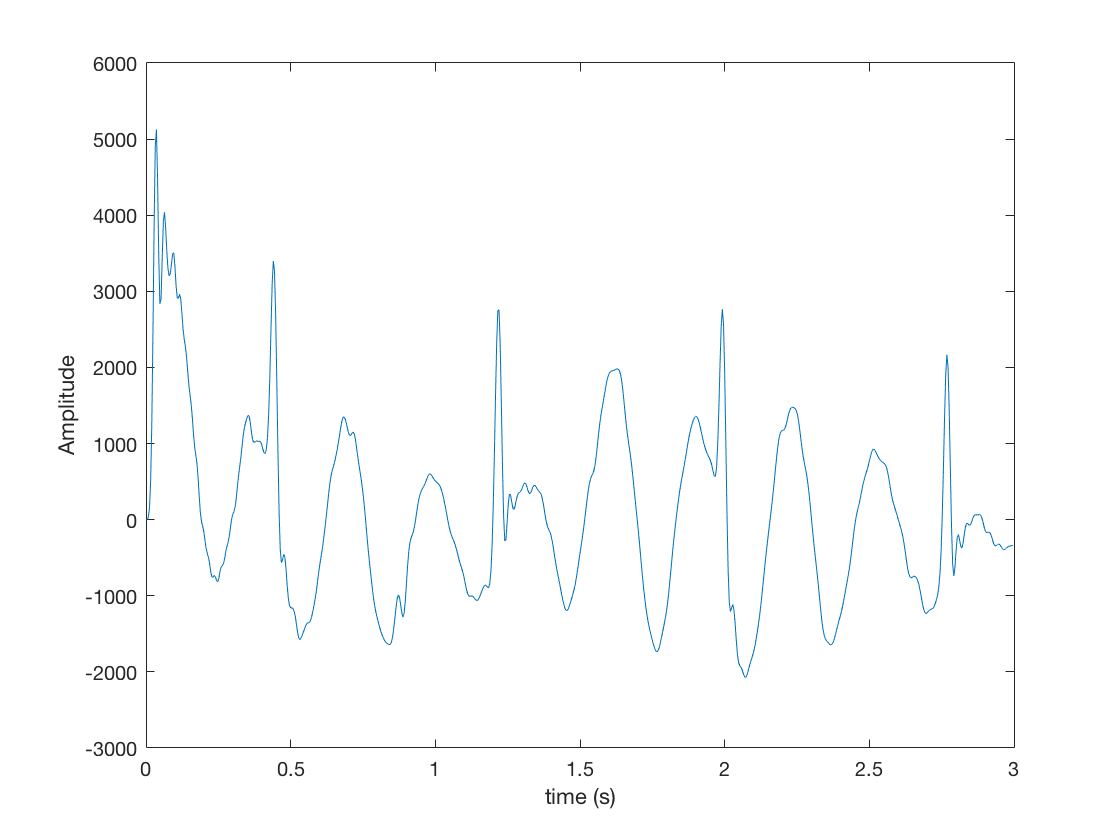

plot(time,signal_high_filtered(1:end_t*Fs))
xlabel('time (s)')
ylabel('Amplitude')


% Final signal is called high_filtered

## **B. Identify ECG components **

clf
N=length(signal_Power_line_filtered);
t=[0:N-1]/fs;

Threshold = 1000;
s = thresh(signal_high_filtered, Threshold);
bpm = rate(signal_high_filtered, Fs, Threshold)

heart_beat =      0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0


bpm = 163.5000

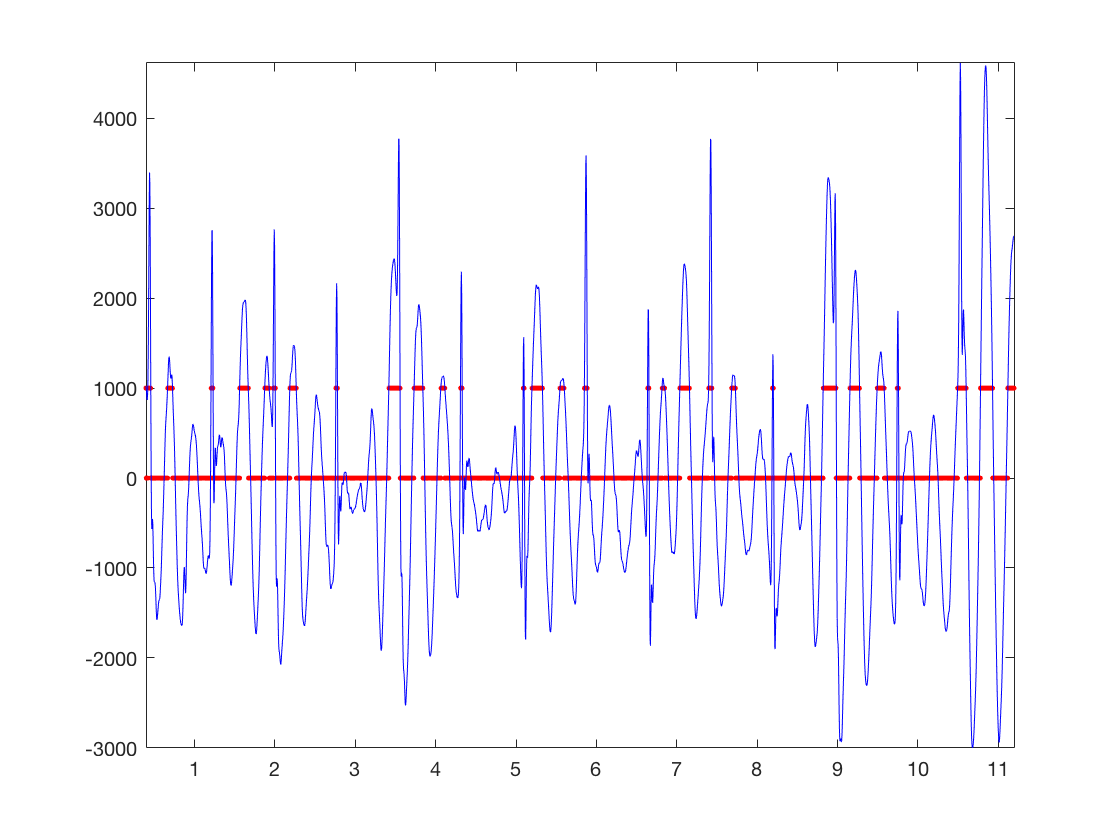


plot(t(100:2800),s(100:2800),'.r');  
hold on
axis tight
plot(t(100:2800),signal_high_filtered(100:2800),'b');  

function bpm = rate(x, Fs, T);
    heart_beat = thresh(x, T) ; % find the heart beat (step 10) % sum to find the number of heart beat occur during the
    % segment (since each heart beat is 1)
    heart_beat = heart_beat/T
    count =0;
    for i = 2:length(heart_beat)
        if heart_beat(i)-heart_beat(i-1)==1 
            count=count+1;
        end 
    end
    % from the sampling frequency, compute the length of the % segment in minute
    minute_length = length(x)/(Fs*60);
    % compute the beats per minute
    bpm = count/minute_length;
end

function s = thresh(x,T)
    % x is input ECG signal
    % T is the threshold
    for i = (1:length(x))
        if x(i) > T
            x(i) = T;
        else
            x(i) = 0;
        end
    end
    s = x;
end